Q-9

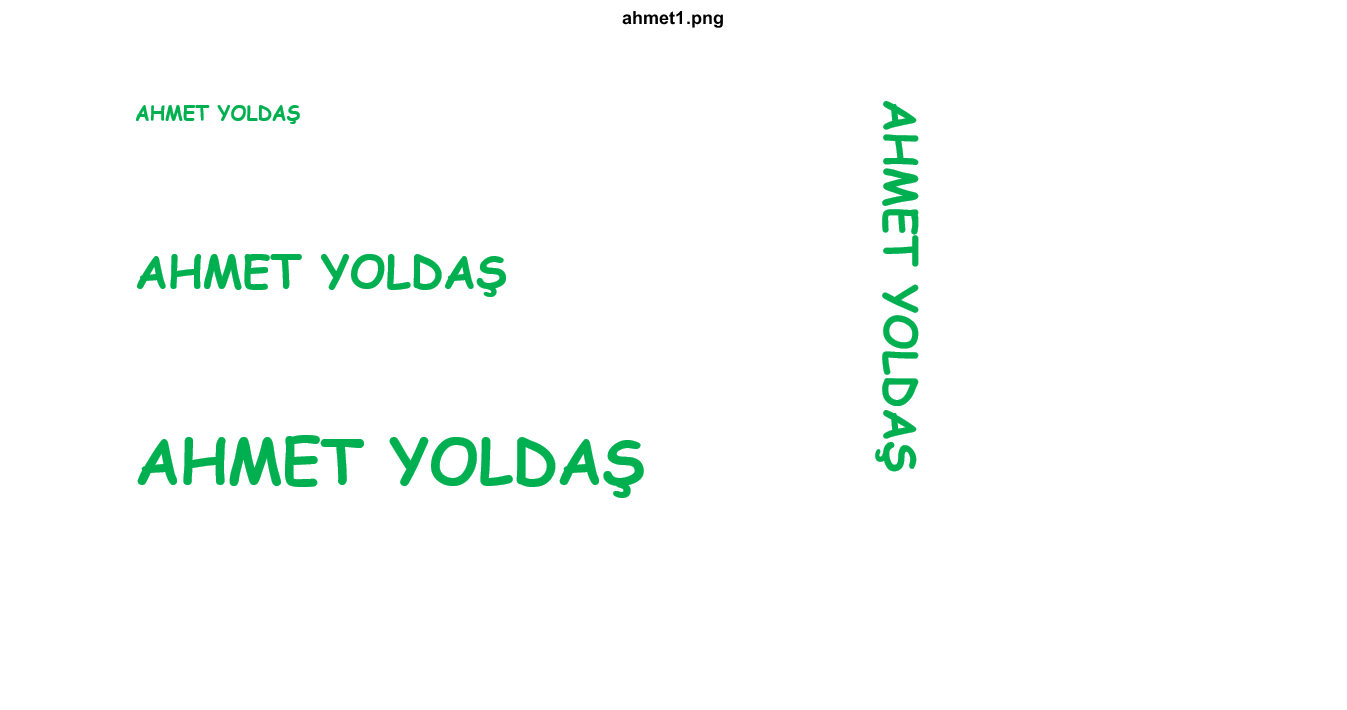

ahmet=imread('C:\Users\ahmet\Desktop\ahmet1.png');
figure;
imshow(ahmet);
title('ahmet1.png');

gray_ahmet=rgb2gray(ahmet);
th_value=128;
ahmet_bin=gray_ahmet>th_value;
% imshow(ahmet_bin);
rahmet_bin=~ahmet_bin

rahmet_bin = 597×1157 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


[rows cols]=size(rahmet_bin)

rows = 597

cols = 1157

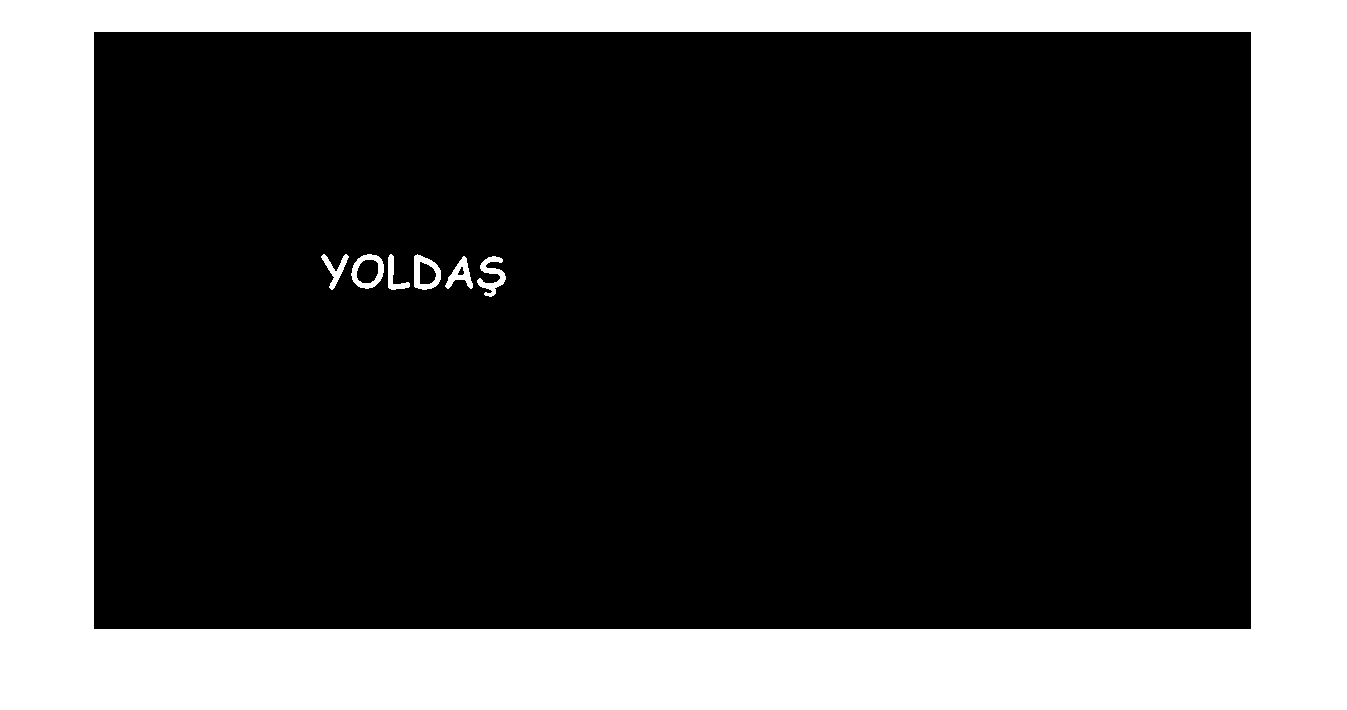


se3=strel("diamond",2);
 ahmet1=imopen(rahmet_bin,se3);
 se4=strel("rectangle",[10 25]);
 ahmet2=imclose(ahmet1,se4);
 se5=strel("rectangle",[10 150]);
 ahmet3=imopen(ahmet2,se5);
 ahmet4=imreconstruct(ahmet3,rahmet_bin);
 figure;
 imshow(ahmet4)